## Answer Part VI 2

clc; clear; close all;

load Filter.mat 

N = input('Enter which file you want\n')

N = 1

str = N + ".ogg"

str = "1.ogg"


snr = input('Enter which file you want to snr\n')

snr = 30

 
[y,Fs] = audioread(str) 

y =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


Fs = 48000

y = y(:,1); 
dt = 1/ Fs 

dt = 2.0833e-05

out = awgn(y , snr) 

out =     0.0285
   -0.0156
    0.0290
    0.0001
   -0.0067
   -0.0334
   -0.0163
    0.0229
   -0.0472
   -0.0337


out=conv(out,Filter); 
t = (0:(length(out)-1)) 

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


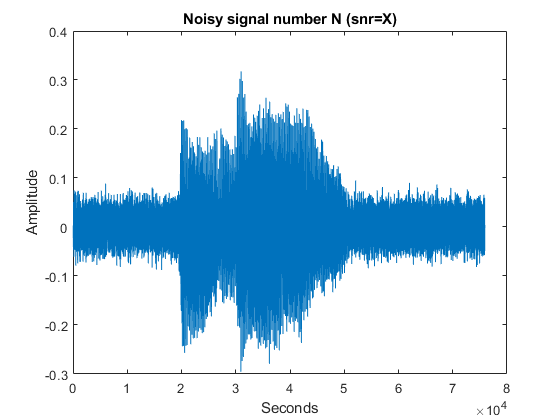

plot(t,out); 
xlabel('Seconds'); 
ylabel('Amplitude');  
title('Noisy signal number N (snr=X)'); 

x = audioread(str)

x =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


temp = awgn(x , 0)

temp =     1.0925
   -0.3734
    0.6666
    0.4396
   -0.0644
    1.2443
    1.0623
   -0.1733
   -0.4992
    0.6746


temp=conv(temp,Filter); 
temp=fft(x,1000)/length(x);
t = (0:999) 

t =      0     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49


plot(t,temp)

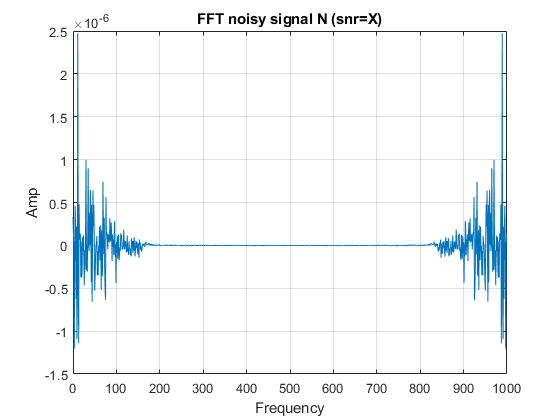

grid on 
xlabel('Frequency'); 
ylabel('Amp');  
title('FFT noisy signal N (snr=X)'); 

SIG = abs(temp)

SIG = 	1.0e+-5 *

    0.0331
    0.0266
    0.0733
    0.1208
    0.1102
    0.0468
    0.0310
    0.1230
    0.1252
    0.1745


Min = min(SIG)

Min = 7.2580e-11

Max = max(SIG)

Max = 2.8884e-06

Avg = mean(SIG)

Avg = 1.1400e-07

Median = median(SIG)

Median = 5.3933e-09

Variance = var(SIG)

Variance = 7.8999e-14